# TradeSpace analysis

Compute the tradespace for the selection of baseline parameters for the payload subsystem of U-Turn spacecraft.

Author: Theo Giverne

This program was created as part of the groupe design project U-Turn for the degree of MSc Astronautics & Space Engineering 

© Cranfield 2024

clear

## Parameters

ApophisLength = 340; % m
AcceptableHitRate = 1;
marker = ["o" "o" "o" "o" "o" "+" "+" "+" "+" "+"];

## Alternatives

### Import Morphological Matrix

opts = spreadsheetImportOptions("NumVariables", 22);

% Specify sheet and range
opts.Sheet = "Feuil1";
opts.DataRange = "A2:V7";

% Specify column names and types
opts.VariableNames = ["Var1", "DeliveredFunction", "DecisionVariables", "AlternativesSolutions", "AlternativesSolutions2", "AlternativesSolutions3", "AlternativesSolutions4", "AlternativesSolutions5", "AlternativesSolutions6", "AlternativesSolutions7", "AlternativesSolutions8", "AlternativesSolutions9", "AlternativesSolutions10", "AlternativesSolutions11", "AlternativesSolutions12", "AlternativesSolutions13", "AlternativesSolutions14", "AlternativesSolutions15", "AlternativesSolutions16", "AlternativesSolutions17", "AlternativesSolutions18", "AlternativesSolutions19"];
opts.SelectedVariableNames = ["DeliveredFunction", "DecisionVariables", "AlternativesSolutions", "AlternativesSolutions2", "AlternativesSolutions3", "AlternativesSolutions4", "AlternativesSolutions5", "AlternativesSolutions6", "AlternativesSolutions7", "AlternativesSolutions8", "AlternativesSolutions9", "AlternativesSolutions10", "AlternativesSolutions11", "AlternativesSolutions12", "AlternativesSolutions13", "AlternativesSolutions14", "AlternativesSolutions15", "AlternativesSolutions16", "AlternativesSolutions17", "AlternativesSolutions18", "AlternativesSolutions19"];
opts.VariableTypes = ["char", "categorical", "string", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, ["Var1", "DecisionVariables"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "DeliveredFunction", "DecisionVariables"], "EmptyFieldRule", "auto");

% Import the data
TradeSpaceMatrix = readtable("/Users/theogiverne/Library/CloudStorage/OneDrive-CranfieldUniversity/Cranfield/Modules/GDP - Group Design Project/TradeSpace AOCSpayload/Trade_Space_Matrix.xlsx", opts, "UseExcel", false)

TradeSpaceMatrix = 6×21 table
           DeliveredFunction              DecisionVariables       AlternativesSolutions    AlternativesSolutions2    AlternativesSolutions3    AlternativesSolutions4    AlternativesSolutions5    AlternativesSolutions6    AlternativesSolutions7    AlternativesSolutions8    AlternativesSolutions9    AlternativesSolutions10    AlternativesSolutions11    AlternativesSolutions12    AlternativesSolutions13    AlternativesSolutions14    AlternativesSolutions15    AlternativesSolutions16    AlternativesSolutions17    AlternativesSolutions18    AlternativesSolutions19
    ________________________________

% Clear temporary variables
clear opts
index_resolution = 1;
index_focalLength = 2;
index_pixelSize = 3;
index_baseLine = 4;
index_maxBlur = 5;
index_exposureTime = 6;

### Create design vector combinations

NumberOfAlternatives = zeros(1, size(TradeSpaceMatrix,1));
for i = 1:numel(NumberOfAlternatives)
    NumberOfAlternatives(i) = sum(~isnan(TradeSpaceMatrix{i, 3:size(TradeSpaceMatrix,2)}));
end

% creating all possible combinations
designVectors = fullfact(NumberOfAlternatives); % [2 3 3 3] -> each number is the number of alternative solution per variable (row)
nbCombination = size(designVectors,1)

nbCombination = 226800

index = (1:1:nbCombination).';

% get vector variable
Alternative_resolution = TradeSpaceMatrix{1, 2+(1:NumberOfAlternatives(1))}.';            % (m)
Alternative_focalLength = (TradeSpaceMatrix{2, 2+(1:NumberOfAlternatives(2))}./1000).';   % (m)
Alternative_pixelSize = TradeSpaceMatrix{3, 2+(1:NumberOfAlternatives(3))}.';             % (m)
Alternative_baseLine = TradeSpaceMatrix{4, 2+(1:NumberOfAlternatives(4))}.';              % (m)
Alternative_maxBlur = TradeSpaceMatrix{5, 2+(1:NumberOfAlternatives(5))}.';               % (%)
Alternative_exposureTime = TradeSpaceMatrix{6, 2+(1:NumberOfAlternatives(6))}.';          % (s)

distance = zeros(nbCombination, 1);
resolutionVect = designVectors(:, index_resolution);
focalLengthVect = designVectors(:, index_focalLength);
pixelSizeVect = designVectors(:, index_pixelSize);
baseLineVect = designVectors(:, index_baseLine);
maxBlurVect = designVectors(:, index_maxBlur);
exposureTimeVect = designVectors(:, index_exposureTime);


resolution = zeros(nbCombination, 1);
focalLength = zeros(nbCombination, 1);
pixelSize = zeros(nbCombination, 1);
baseLine = zeros(nbCombination, 1);
maxBlur = zeros(nbCombination, 1);
exposureTime = zeros(nbCombination, 1);

for i = 1:nbCombination
    resolution(i) = Alternative_resolution(resolutionVect(i));
    focalLength(i) = Alternative_focalLength(focalLengthVect(i));
    pixelSize(i) = Alternative_pixelSize(pixelSizeVect(i));
    baseLine(i) = Alternative_baseLine(baseLineVect(i));
    maxBlur(i) = Alternative_maxBlur(maxBlurVect(i));
    exposureTime(i) = Alternative_exposureTime(exposureTimeVect(i));

end


## Criteria

criteriaMatrix = zeros(size(designVectors,1),10);

### Distance

$Z=\frac{f\cdot b}{D\cdot d}$, with f the focal length, b the baseline, Z the distance to Apophis, d the pixel size and D the disparity or $\frac{L_{\textrm{Apophis}} }{r}$ 

for i = 1:nbCombination
    r = resolution(i);
    f = focalLength(i);
    d = pixelSize(i);
    b = baseLine(i);
    D = ApophisLength/r;
    distance(i) = (f*b)/(D*d); 
end
T = table(index, resolution, focalLength, pixelSize, baseLine, maxBlur, exposureTime, distance);

### Risk 

Risk is defined by the probability of dust particule hitting the s/c at a given distance

% Parameters
ParticuleDensityInit = 100e5; % particules per m2 emtited at the surface of Apophis
scArea = 0.3*0.2; % (m2)
k = AcceptableHitRate; % hits

%distance = 10:10:10000; % distance from Apophis nucelus

SphereAreaAtDistance = 4*pi*distance.^2; % (m2)
ParticuleDensityAtDistance = ParticuleDensityInit./SphereAreaAtDistance; % particules/m2
nbParticulesInSCArea = ParticuleDensityAtDistance*scArea;

#### Poisson distribution

$P=\frac{\lambda^ke^{-\lambda}}{k!}$, |ambda is the number of event for a given interval, so here the number of particule in the area covered by the SC. k is the number of time up to which the even we want the probablity happens, to assess the risk we will start with the likelyhood of being hit once. So the probablity of being hit more than once is $1-P$.

hitProbability = 1 - poisscdf(k, nbParticulesInSCArea);

Associating hit probability to each scenario

T.hitProbability = hitProbability;

#### Minimum required jitter


$$\textrm{jitter}=\;\frac{1}{E}\cdot \textrm{asin}\left(\frac{\Delta d}{Z}\right)$$


deltaD = resolution.*maxBlur;
jitter_rad = 1./exposureTime .* asin(deltaD./distance); % (rad/s)
jitter_deg = rad2deg(jitter_rad); % (°/s)
T.jitter = jitter_deg;

#### Data rate

data rate is defined as the inverse of the baseline as the baseline is directly related to the frame rate, lower baseline = higher frame rate => more pictures more data rate for downloading 

R = 1./baseLine;

### Complexity


$$C=\frac{f\cdot R}{\sqrt[3]{\textrm{Jitter}}}$$
 

C = (R.*focalLength)./jitter_rad.^1/3;
normC = C./max(C);
T.RelativeComplexity = 1 - (abs(10*log10(normC))/max(abs(10*log10(normC))));

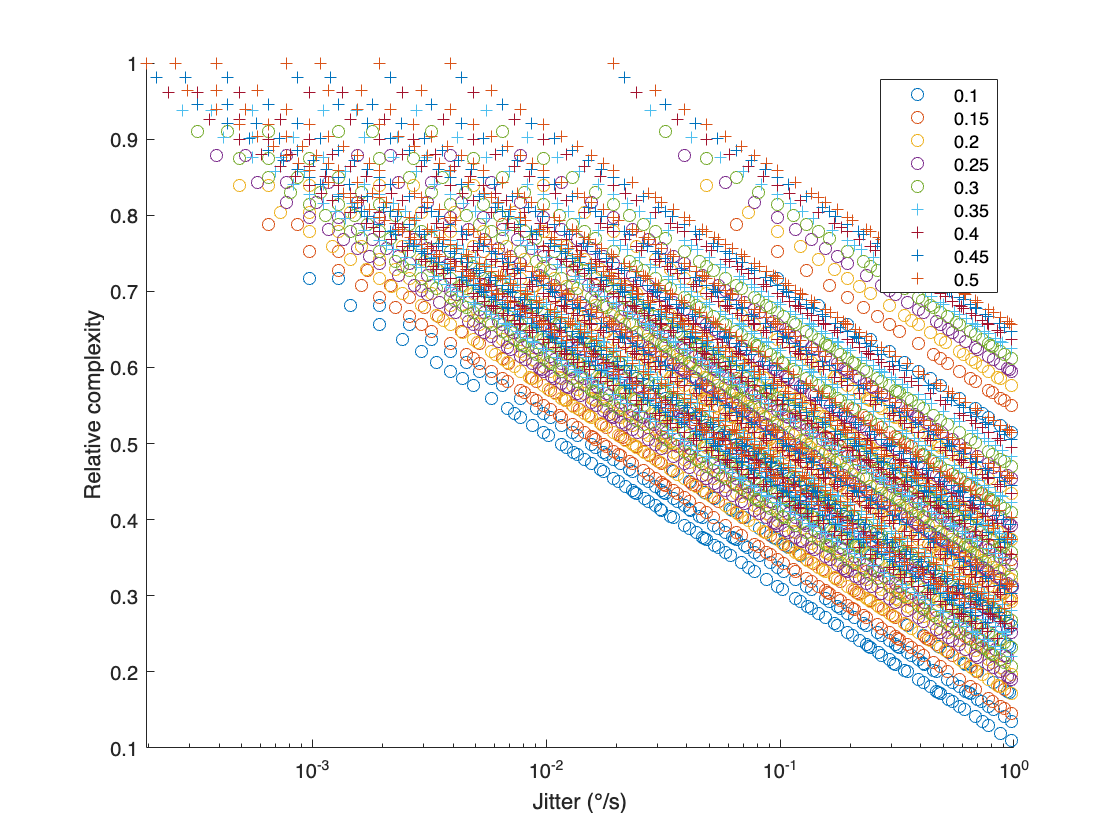

figure
for i = 1:numel(Alternative_focalLength)
    f = Alternative_focalLength(i);
    X = T(ismember(T.focalLength, f), :).jitter;
    Y = T(ismember(T.focalLength, f), :).RelativeComplexity;
    scatter(X, Y, marker(i)); hold on
end
set(gca,'xscale','log')
xlim([0, 1])
legend(string(Alternative_focalLength), Location="northeast")
xlabel('Jitter (°/s)')
ylabel('Relative complexity')

### Risk/Reward

 
$$\textrm{Reward}=\;1-||\frac{\textrm{Resolution}}{1-\textrm{maxBlur}}||$$


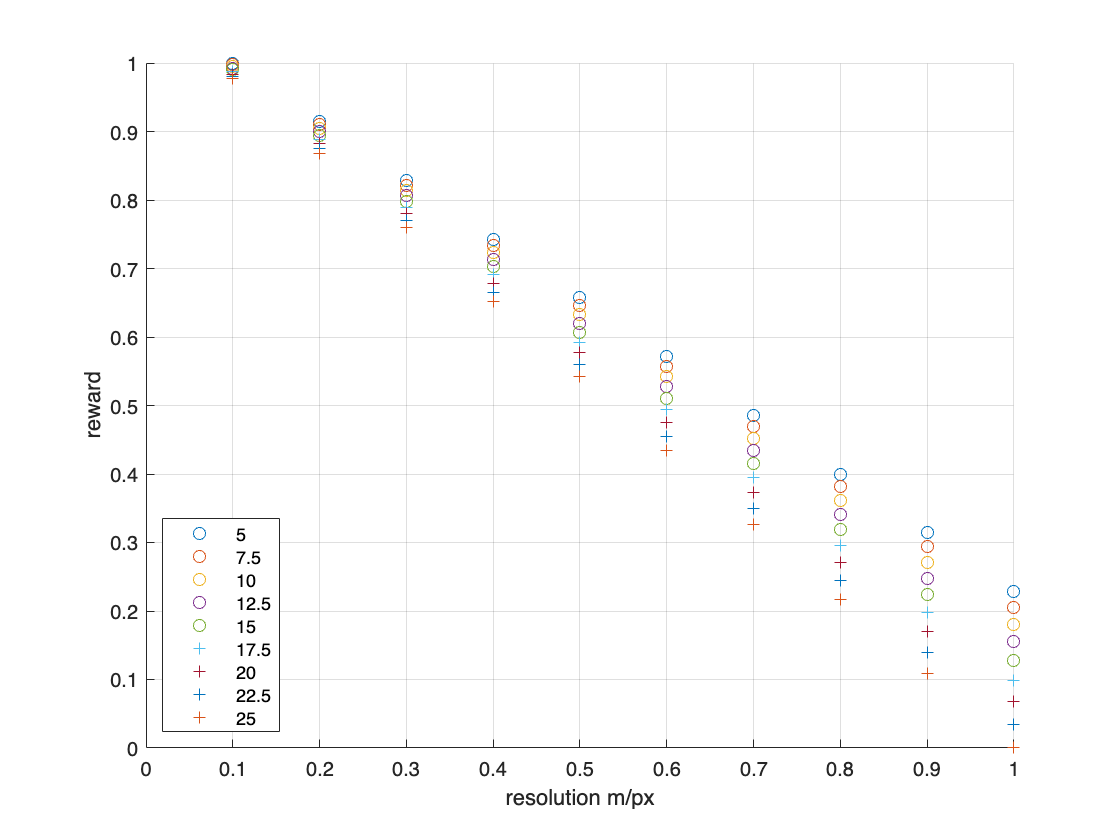

reward =T.resolution./(1-T.maxBlur);
norm_reward = 1 - (reward-min(reward))./(max(reward)-min(reward));

figure
T.Reward = norm_reward;
for i = 1:numel(Alternative_maxBlur)
    res = Alternative_maxBlur(i);
    X = T(ismember(T.maxBlur, res), :).resolution;
    Y = T(ismember(T.maxBlur, res), :).Reward;
    scatter(X, Y, marker(i)); hold on
end
xlabel('resolution m/px')
ylabel('reward')
xlim([0,1])
legend(string(Alternative_maxBlur*100), Location="southwest")
grid
hold off


$$\textrm{Risk}=1-||10\log_{10} \left(\textrm{HitProbability}\right)||$$


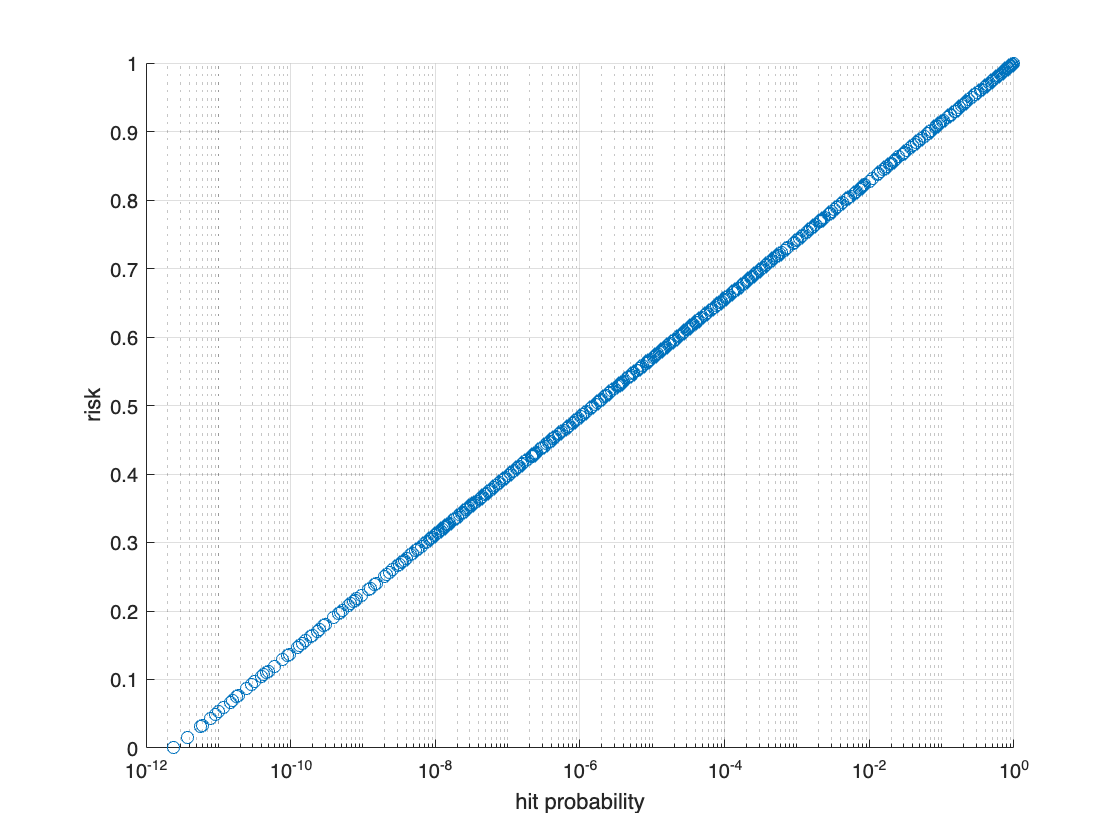

risk = -(10.*log10(T.hitProbability));
norm_risk = 1 - risk./max(risk);
T.Risk = norm_risk;
scatter(T.hitProbability, norm_risk); hold on
xlabel('hit probability')
ylabel('risk')
set(gca,'xscale','log')
grid
hold off


$$\textrm{Risk}=\frac{\left\|{\textrm{hitProbability}}_{\textrm{dB}} \right\|+\left(1-\left\|\log \left(\textrm{RelativeComplexity}\right)\right\|\right)}{2}$$


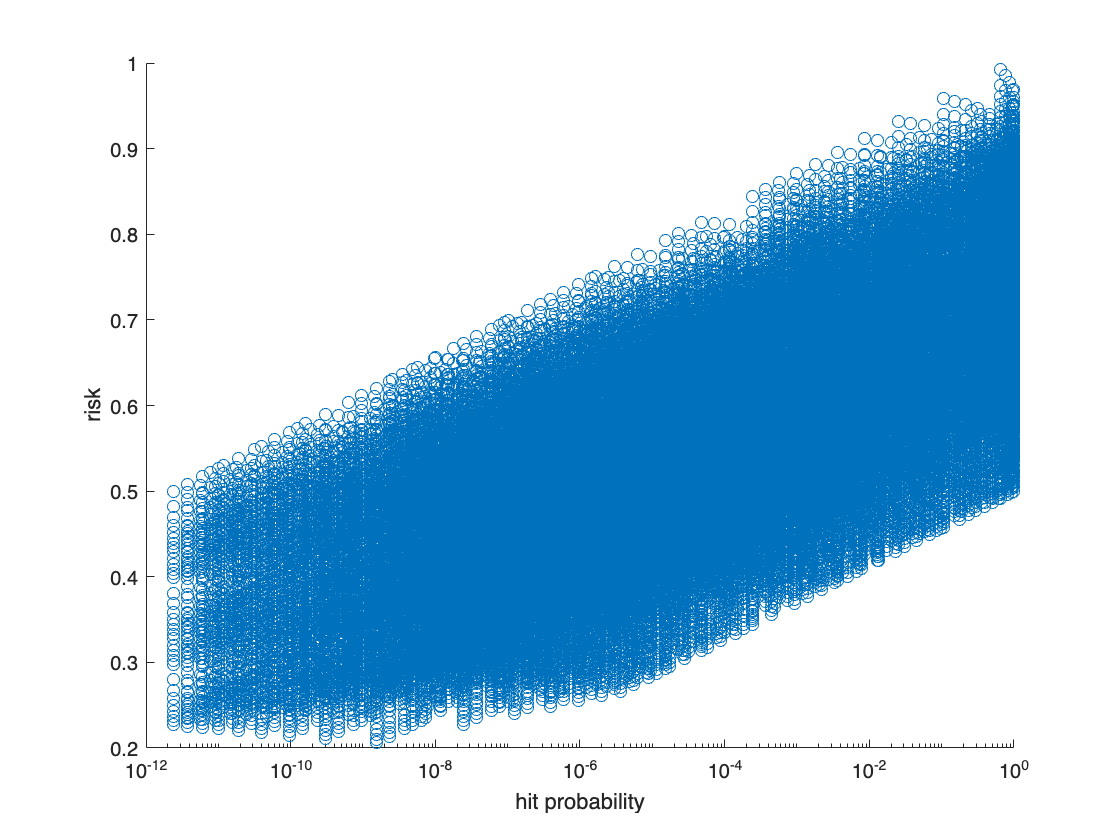

% Risk and complexity
figure
T.RiskAndComplexity = ( T.Risk + T.RelativeComplexity )/2;
scatter(T, "hitProbability", "RiskAndComplexity"); hold on
xlabel('hit probability')
ylabel('risk')
set(gca,'xscale','log')
hold off

## Risk with complexity vs reward

% create the pareto optimum border

rewards = unique(T.Reward);

for i = 1:numel(rewards)
    A = T(ismember(T.Reward, rewards(i)),:);
    A = sortrows(A, "RiskAndComplexity", "ascend");
    B(i,:) = A(1,:);
end

Bnumel = numel(B.index);
j = 0;

for i = 1:Bnumel
    if B.RiskAndComplexity(i) <= min(B.RiskAndComplexity(i:Bnumel))
        j = j+1;
        B2(j,:) = B(i,:);
    end
end

B = B2; % vector for the pareto optimum
clear B2

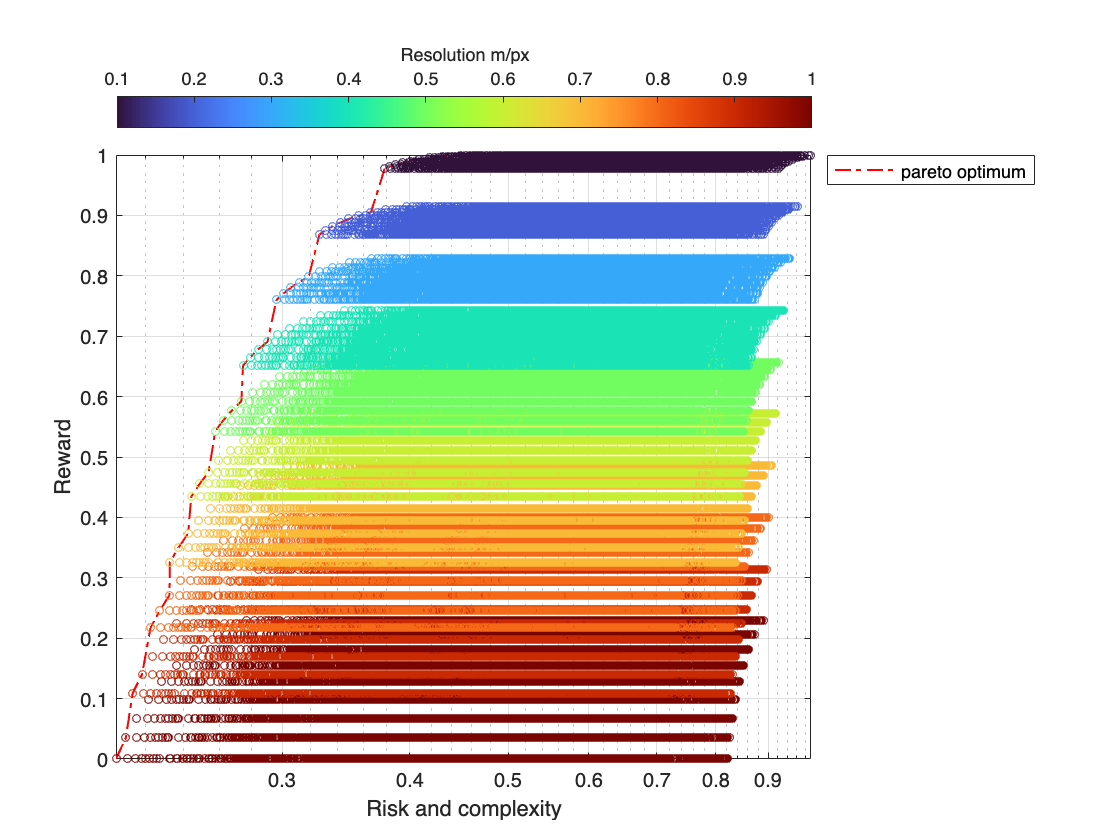

plot(B.RiskAndComplexity, B.Reward, 'r-.', LineWidth=1); hold on
s = scatter(T, "RiskAndComplexity", "Reward", ColorVariable="resolution", SizeData=15, Marker='o'); hold on
colormap(gca, "turbo");
xlabel('Risk and complexity');
ylabel('Reward');
set(gca,'xscale','log');
grid on;
c = colorbar('Location','northoutside');
c.Label.String = 'Resolution m/px';
%c.Ruler.Exponent=0;
legend("pareto optimum", "Location","bestoutside");
dtt = s.DataTipTemplate;
for i = 1:size(T,2)
    dtt.DataTipRows(i).Label = string(T.Properties.VariableNames(i));
    dtt.DataTipRows(i).Value = T.(i);
end
hold off

sortrows(B(B.Reward >= 0.8 & B.Reward <= 1 | ismissing(B.Reward),:), "index", "ascend")

ans = 16×14 table
    index    resolution    focalLength    pixelSize    baseLine    maxBlur    exposureTime    distance    hitProbability     jitter     RelativeComplexity    Reward      Risk      RiskAndComplexity
    _____    __________    ___________    _________    ________    _______    ____________    ________    ______________    ________    __________________    _______    _______    _________________
     4411       0.1            0.1          1e-06        100         0.05        0.001         2941.2       1.

## Hit probability details

% Parameters
ParticuleDensityInit = 100e6% particules/m2 emtited at the surface of Apophis

ParticuleDensityInit = 100000000

scArea = 0.3*0.2; %(m2)
k = 1; % AcceptableHitRate

d = 10:1:10000; % distance from Apophis nucelus (m)

SphereAreaAtDistance = 4*pi*d.^2; % m2
ParticuleDensityAtDistance = ParticuleDensityInit./SphereAreaAtDistance; % particule/m2
nbParticulesInSCArea = ParticuleDensityAtDistance.*scArea;
hitProbability = 1-poisscdf(k, nbParticulesInSCArea);


#### Poisson distribution

$P=\frac{\lambda^ke^{-\lambda}}{k!}$, lambda is the number of event for a given interval, so here the number of particule in the area covered by the SC. k is the number of time up to which the even we want the probablity happens in the interval of time, to assess the risk we will start with the likelyhood of being hit once. So the probablity of being hit more than once is 1-$P$.

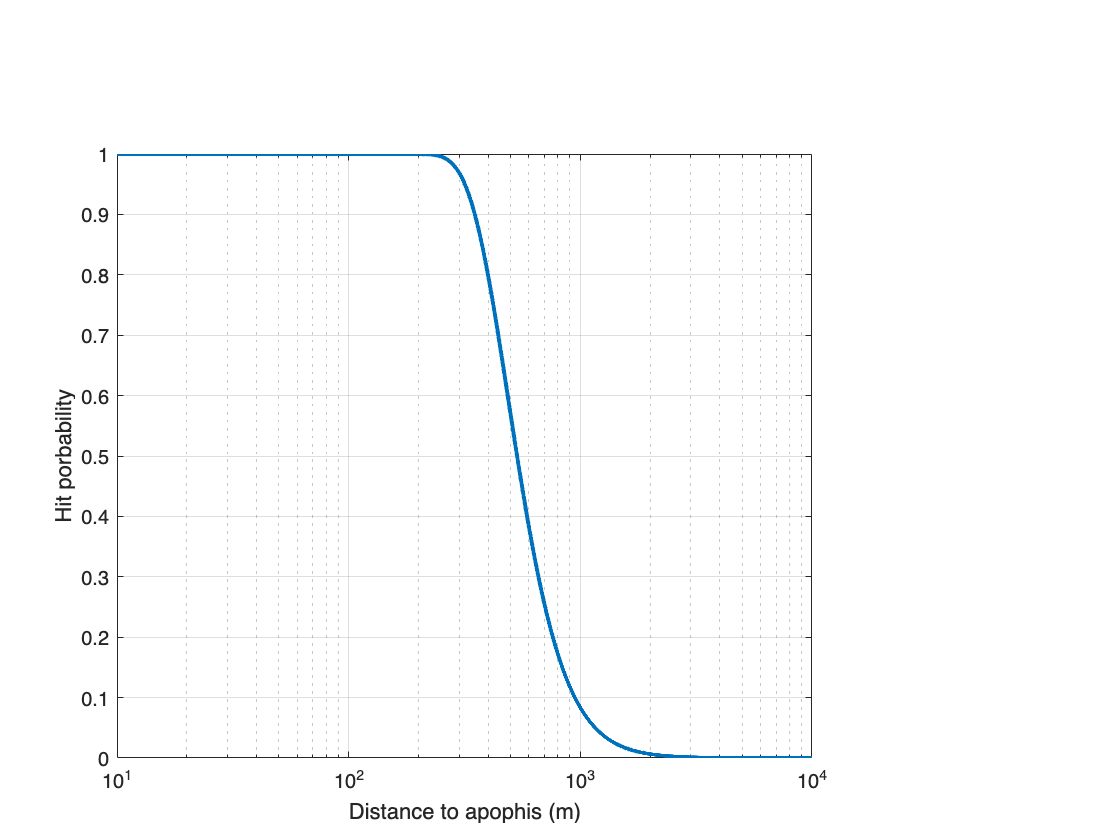

semilogx(d, hitProbability,'LineWidth',2); hold on
grid on
xlabel('Distance to apophis (m)');
ylabel("Hit porbability")
hold off

## Roche limit

Souchay, J. & Souami, D. & Lhotka, Christoph & Puente, V. & Folgueira, Marta. (2014). Rotational changes of the asteroid 99942 Apophis during the 2029 close encounter with Earth. Astronomy & Astrophysics. 563. A24. 10.1051/0004-6361/201322364. 

"For the density range above (ρA = [2.6–2.8]), Fig. 1 shows that the Roche limit is on the order of 1.6 *R*E, a distance that corre- sponds roughly to 26% of the minimum estimated distance of the encounter. For a density of ρA = 1 and ρA = 0.5, the Roche limit becomes 2.2*R*E and 2.8*R*E respectively, which correspond to 38% and 47% of this distance. Scheeres et al. (2005) mention the density of 0.44, for which the closest approach uncertainty ellipse lies within the Roche limit. According to our calcula- tions, the nominal value of the closest distance (38 326 km) is still twice more than the nominal Roche limit.  As mentioned by Scheeres et al. (2005), if the asteroid’s bulk density is greater than 1, we can expect that the asteroid will most likely not disrupt catastrophically, but that for densities be- low this value, terrestrial torques should cause strong angular ac- celerations and particles on the surface should experience large fractional changes in local gravity. 